% Download and create openminds schemas
om.update()

% Import schemas from core model
import openminds.core.*

% Create a new demo subject
subject1 = Subject('species', 'musMusculus', 'biologicalSex', 'male', 'lookupLabel', 'demo_subject1');
disp(subject1)

  Subject (https://openminds.ebrains.eu/core/Subject) with properties:

         biologicalSex: male  (Controlled Term)
    internalIdentifier: ""
              isPartOf: [None]  (SubjectGroup)
           lookupLabel: "demo_subject1"
               species: [musMusculus]  (Controlled Term)
          studiedState: [None]  (SubjectState)

  Required Properties: species, studiedState


% Create and display a new subject state
subjectStateA = SubjectState('ageCategory', 'adult', 'attribute', 'alive', 'lookupLabel', 'demo-subject-stateA');
disp(subjectStateA)

  SubjectState (https://openminds.ebrains.eu/core/SubjectState) with properties:

         additionalRemarks: ""
                       age: [None]  (QuantitativeValue, QuantitativeValueRange)
               ageCategory: adult  (Controlled Term)
                 attribute: alive  (Controlled Term)
             descendedFrom: [None]  (

% Add subject state to the subject
subject1.studiedState = subjectStateA;

set linked property of openminds.core.Subject


disp(subject1)

  Subject (https://openminds.ebrains.eu/core/Subject) with properties:

         biologicalSex: male  (Controlled Term)
    internalIdentifier: ""
              isPartOf: [None]  (SubjectGroup)
           lookupLabel: "demo_subject1"
               species: [musMusculus]  (Controlled Term)
          studiedState: demo-subject-stateA  (SubjectState)

  Required Properties: species, studiedState


% Create a metadata collection and add the subject
mdc = openminds.MetadataCollection()

mdc =   MetadataCollection with properties:

    metadata: [0×1 containers.Map]
       graph: [1×1 digraph]


mdc.add(subject1)

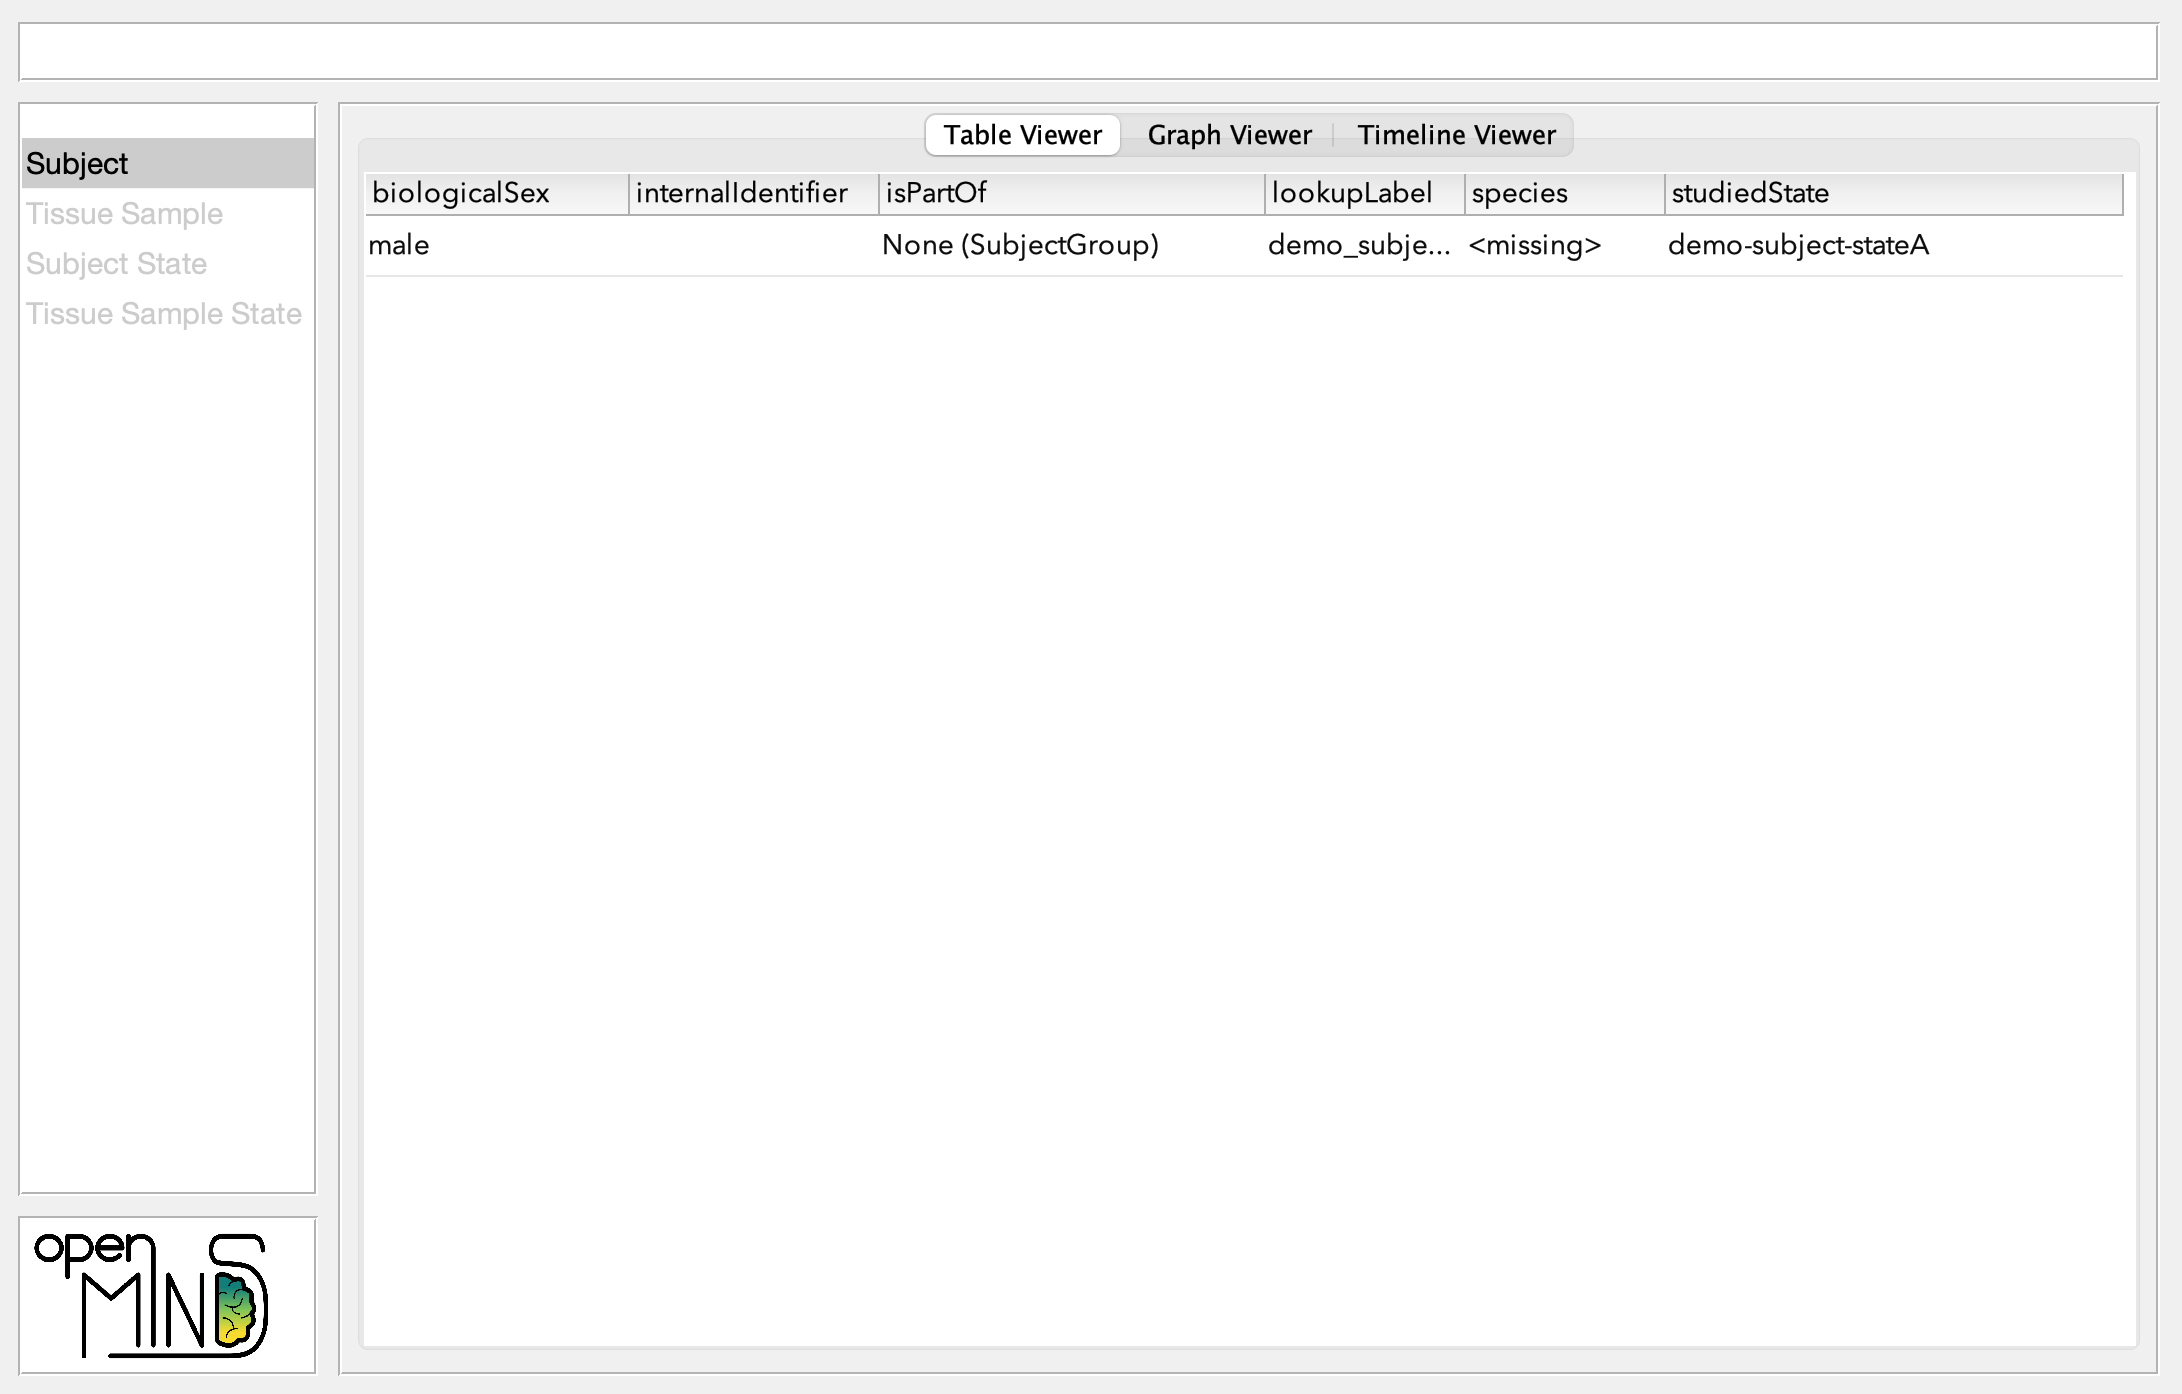

% Open the metadata collection in the App
om.ModelBuilder(mdc)